# Assignment 1 – Bonus App

January 30, 2024

Christopher Maxwell

Z23637240

## Select an Image

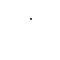

[fileName, filePath] = uigetfile({'*.jpg;*.png;*.bmp;*.gif', 'All Image Files'}, 'Select an image');
fullFileName         = fullfile(filePath, fileName);
inputImage           = imread(fullFileName);

imshow(inputImage);       

## Select a Filter

stringToPrint = sprintf('Hey dude! What''s up? Check it...\n\nSelect one of the following filters by entering\nits number in the Command Window:');
disp(stringToPrint)

Hey dude! What's up? Check it...

Select one of the following filters by entering
its number in the Command Window:



% filter choices
disp('1. Gaussian Filter')

1. Gaussian Filter


disp('2. Median Filter')

2. Median Filter


disp('3. 2D Adaptive Noise-Removal')

3. 2D Adaptive Noise-Removal



filterOption = input('Enter the number listed in the output window here: ');

switch filterOption
    case 1
        filteredImage = imgaussfilt(inputImage, 2);  % Gaussian Filter
    case 2
        filteredImage = medfilt2(inputImage);        % Median Filter
    case 3
        filteredImage = wiener2(inputImage);         % wiener2 Filter
    otherwise
        disp('Sorry, wrong filter choice. It''s all good, try again.')
        disp('Here is your original unfiltered image:')
        filteredImage = inputImage;
end

## Display Image

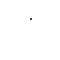

imshow(filteredImage);

## Save Image

[fileName, filePath] = uiputfile({'*.jpg';'*.png';'*.bmp';'*.gif'}, 'Save your image');
fullFileName         = fullfile(filePath, fileName);

imwrite(filteredImage, fullFileName);